clear; clc;
close all;

%% Text Size
set(0,'DefaultAxesFontsize',8);
set(0,'DefaultTextFontsize',8);

%% Text Fonts
set(0,'DefaultTextFontname','Arial');
set(0,'DefaultAxesFontname','Arial');

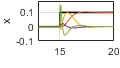

load("data\fig2_robot_test.mat");

figsize = [10,10,2,1.8];
figpos = [0.32 0.39 0.63 0.6];

figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

p1 = plot(tstep,r_step(1,:), 'k');
p1.LineWidth = 1.2;
hold on;
grid on;
p2 = plot(tstep,x_step);
% xlabel('t');
xlim([13 20]);
% xticks([0.4 0.5]);
ylim([-0.1 0.18]);
ylabel('x');

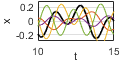


figure('Color',[1 1 1]);
set(gcf,'unit','centimeters','position',figsize);
set(gca,'Position', figpos);
set(gcf,'Visible','on');

p1 = plot(tsin,r_sin(1,:), 'k');
p1.LineWidth = 1.2;
hold on;
grid on;
p2 = plot(tsin,x_sin);
% for i = 1:10
%     p2(i).Color = colors(i,:);
% end
% xlabel('t');
xlim([10 15]);
ylim([-0.29 0.29]);
xlabel('t', 'Position', [12.5 -0.4]);
ylabel('x');

## function

function [SinusoidBus, busin, SinusoidBustar, busintar] = create_bus_input(input, tar, dt)
    inputDim = 1;    
    tarDim = 1; 
    
    % input = input*2-1;
    [numx, ~] = size(input);

    time = 0:dt:(numx-1)*dt;

    clear elems;
    for j = 1:inputDim
        elems(j) = Simulink.BusElement;
        elems(j).Name = ['x' num2str(j)];
    end
    SinusoidBus = Simulink.Bus;
    SinusoidBus.Elements = elems;
    clear busin;
    busin.x1 = timeseries(input,time);

    clear elems;
    for j = 1:tarDim
        elems(j) = Simulink.BusElement;
        elems(j).Name = ['x' num2str(j)];
    end
    SinusoidBustar = Simulink.Bus;
    SinusoidBustar.Elements = elems;
    clear busintar;
    busintar.x1 = timeseries(tar,time);

end

function [SinusoidBus, busin, SinusoidBustar, busintar] = create_buscontrol_input(input, tar, dt)
    inputDim = 4;    
    tarDim = 1; 
    
    % input = input*2-1;
    [numx, ~] = size(input);

    time = 0:dt:(numx-1)*dt;

    clear elems;
    for j = 1:inputDim
        elems(j) = Simulink.BusElement;
        elems(j).Name = ['x' num2str(j)];
    end
    SinusoidBus = Simulink.Bus;
    SinusoidBus.Elements = elems;
    clear busin;
    busin.x1 = timeseries(input,time);
    busin.x2 = timeseries(0*input,time);
    busin.x3 = timeseries(0*input,time);
    busin.x4 = timeseries(0*input,time);

    clear elems;
    for j = 1:tarDim
        elems(j) = Simulink.BusElement;
        elems(j).Name = ['x' num2str(j)];
    end
    SinusoidBustar = Simulink.Bus;
    SinusoidBustar.Elements = elems;
    clear busintar;
    busintar.x1 = timeseries(tar,time);

end